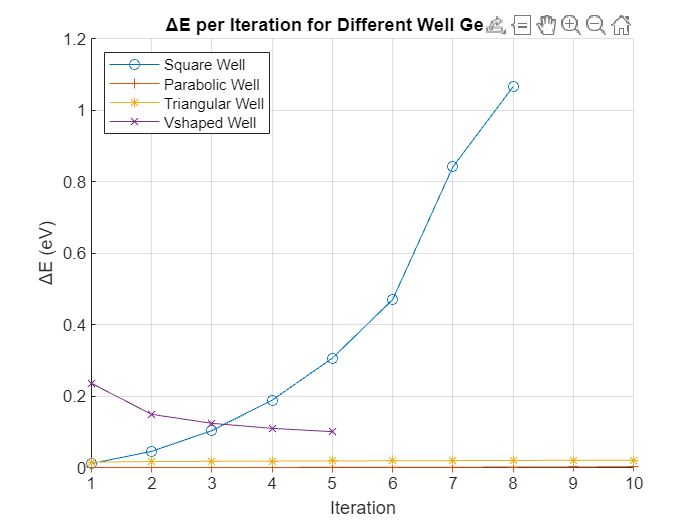

% Define the data for each well
squareWell = [0.044939, 0.056103, 0.17932, 0.22441, 0.40174, 0.50493, 0.70934, 0.89765, 1.0965, 1.4026, 1.5498, 2.0197, 2.749, 3.5906, 4.5443, 5.6103];
parabolicWell = [0.099989, 0.1, 0.29995, 0.3, 0.49986, 0.5, 0.69973, 0.7, 0.89955, 0.9, 1.0993, 1.1, 1.2991, 1.3, 1.4988, 1.5, 1.6984, 1.7, 1.898, 1.9];
triangularWell = [0.24592, 0.26086, 0.4423, 0.45891, 0.603, 0.62029, 0.74497, 0.76276, 0.8747, 0.89296, 0.99554, 1.0143, 1.1095, 1.1287, 1.2179, 1.2376, 1.3217, 1.3419, 1.4216, 1.4422];
vshapedWell = [0.1802, 0.41605, 0.57683, 0.72572, 0.85452, 0.97813, 1.0908, 1.2004, 1.3026, 1.4028];

% Function to compute delta energy with skipping one element
computeDelta = @(data) data(2:2:end) - data(1:2:end-1);

% Compute delta energy for each set
deltaSquareWell = computeDelta(squareWell);
deltaParabolicWell = computeDelta(parabolicWell);
deltaTriangularWell = computeDelta(triangularWell);
deltaVshapedWell = computeDelta(vshapedWell);

% Plotting
figure;
hold on;
plot(deltaSquareWell, '-o', 'DisplayName', 'Square Well');
plot(deltaParabolicWell, '-+', 'DisplayName', 'Parabolic Well');
plot(deltaTriangularWell, '-*', 'DisplayName', 'Triangular Well');
plot(deltaVshapedWell, '-x', 'DisplayName', 'Vshaped Well');
hold off;

% Enhancing the plot
xlabel('Iteration');
ylabel('ΔE (eV)');
title('ΔE per Iteration for Different Well Geometries');
legend('Location', 'northwest');
legend('show');
grid on;